# **Tutorial: 2D Eigenvalue Problem**

In this problem, we will be investigating a $2 \times 2$ square matrix, $\mathbf{M}$, taking on the following form:


$$\mathbf{M} = \pmatrix{\theta_1+\theta_2 & -\theta_2 \cr -\theta_2 & \theta_2}$$


whereby $\theta_1$ and $\theta_2$ are the matrix elements. Examples of matrices taking on such form include the Stiffness matrix in the [Tuned Mass Damping system](https://link.springer.com/article/10.1007/s40091-016-0136-7). The matrix elements take on fixed values but are unknown to the analyst, and hence, $\theta_1$ and $\theta_2$ are to be estimated.

In the conventional "forward" Eigenvalue problem, the Eigenvalues, $\lambda$, are calculated from a general $N \times N$square matrix, $\mathbf{Q}$, whose matrix elements are known quantities. Every Eigenvalue of $\mathbf{Q}$ has its associated $N \times 1$ Eigenvector, $\vec{v}$. For any Eigenvalue problem, the relationship between $\mathbf{Q}$, $\vec{v}$, and $\lambda$ is as such:


$$\mathbf{Q} \vec{v} = \lambda \vec{v}$$


To solve for the Eigenvalues, $\lambda
$, for a general $N \times N$square matrix, $\mathbf{Q}$, the above equation is first re-expressed into the following form:


$$[\mathbf{Q} - \mathbf{I}\lambda]\vec{v} = \vec{0}$$


whereby $\vec{0}$ is the zero vector, and $\mathbf{I}$ is the $N \times N$ Identity matrix. Following which, the determinant of $[\mathbf{Q} - \mathbf{I}\lambda]$ is calculated and equated to $0$ to yield a polynomial equation as a function of $\lambda$. From there, the solution(s) of $\lambda$ is/are obtained analytically.

For the case of $\mathbf{M}$, there are $2$ solutions of $\lambda$, each taking on the following respective mathematical expressions:


$$\lambda_{1}^{model} = \frac{(\theta_1+2\theta_2)+\sqrt{{\theta_1}^2+4{\theta_2}^2}}{2}$$



$$\lambda_{2}^{model} = \frac{(\theta_1+2\theta_2)-\sqrt{{\theta_1}^2+4{\theta_2}^2}}{2}$$


Putting everything in a physcial context, the square matrix $\mathbf{M}$ represents a hypothetical physical system and its Eigenvalues $\lambda$ represent the possible measurements/observations that can be made from that system. In this problem, the above mathematical models for $\lambda_{1}^{model}$ and $\lambda_{2}^{model}$ are assumed to be perfect. However, the measurements/observations, $\lambda_{i}^{noisy}$, are affected by noise, $\epsilon_{i}$ (for $i = 1,2$), whereby:

 
$$\lambda_{1}^{noisy} = \frac{(\theta_1+2\theta_2)+\sqrt{{\theta_1}^2+4{\theta_2}^2}}{2} + \epsilon_1$$



$$\lambda_{2}^{noisy} = \frac{(\theta_1+2\theta_2)-\sqrt{{\theta_1}^2+4{\theta_2}^2}}{2} + \epsilon_2$$


This problem is often referred in literature as model updating which is an inverse problem whereby the parameters of interest (in this case, $\theta_1$ and $\theta_2$) are calculated based on the observations (in this case, $\lambda_{1}^{noisy}$ and $\lambda_{2}^{noisy}$) made from the system of interest. In other words, the matrix elements, $\theta_1$ and $\theta_2$, are being calculated from the model output contrary to the forward problem as described earlier.

### Problem Statement:

In this problem, the Posterior distribution is Bi-modal (two distinct peaks). The purpose of this tutorial is to analyse and compare the performance of the MCMC, TMCMC, and the SMC sampler in the estimation of the matrix elements, $\theta_1$ and $\theta_2$, from a 2D Bi-modal Poterior distribution. 

## 1) Observations

We assume $15$ independent observations of the Eigenvalues are available. The real values of $\theta_1$ and $\theta_2$ are unknown to the analyst. It is also assumed that the observations, $ \lambda_{1}^{noisy}$ and $\lambda_{2}^{noisy}$, are each corrupted with their respective noise, $\epsilon_1$ and $\epsilon_2$. In this problem, $\epsilon_1$ is modelled as Normal distribution with mean $0$ and standard deviation $1$, while $\epsilon_2$ is modelled as Normal distribution with mean $0$ and standard deviation $0.1$. 

The Model function is also defined as a handle function. Details to the function can be found in the file titled: "model.m".

% True values of Thetas:
ndims = 2; % number of unknown parameters to be estimated
theta_1 = 0.5;
theta_2 = 1.5;
theta = [theta_1,theta_2];

% Number of observations:
Nobservations = 15;  

% Standard deviation of the noise:
NoiseStandardDeviation_1 = 1;
NoiseStandardDeviation_2 = 0.1;
NoiseStandardDeviation = [NoiseStandardDeviation_1, NoiseStandardDeviation_2];

% Defining the Noise associated with the Eigenvalues:
EigenvalueNoise_1 = randn(Nobservations,1)*NoiseStandardDeviation_1;
EigenvalueNoise_2 = randn(Nobservations,1)*NoiseStandardDeviation_2;
EigenvaluesNoise = [EigenvalueNoise_1, EigenvalueNoise_2];

% Defining the Eigenvalue function handle without Noise:
EigenvaluesPerfect = @(x) model(x);

% Defining the Eigenvalues corrupted with Noise:
Eigenvalues = EigenvaluesPerfect(theta) + EigenvaluesNoise;

The observations are represented in the form of a 2D scatter plot diagram.

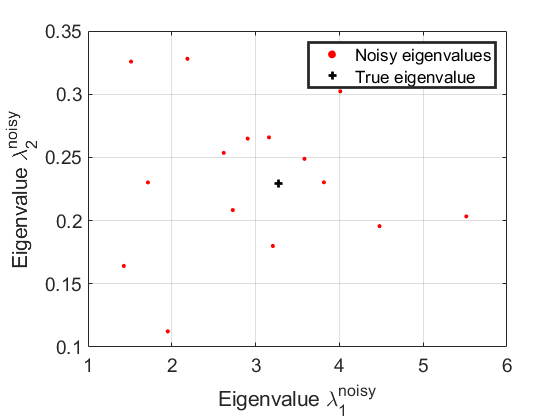

% To plot the 2D scatter plot of the model:
figure;
h1 = scatter(Eigenvalues(:,1), Eigenvalues(:,2), 10, 'r', 'filled');
hold on
box on
grid on
plot(3.2702, 0.2293, 'k +',"LineWidth", 2);
xlabel('Eigenvalue \lambda^{noisy}_1', 'Fontsize', 20)
ylabel('Eigenvalue \lambda^{noisy}_2', 'Fontsize', 20)

% To customize the figure:
h=gca;
h.Box='on';
h.FontSize=14;
legend('Noisy eigenvalues', 'True eigenvalue','LineWidth',2)
hold off

## 2) Bayesian Model Updating

Bayesian Model Updating is a form of model updating based on Bayesian Inference. The parameters of interest are treated as random variables with a joint Probability distribution function associated with them. Bayesian Inference devises a joint Probability distribution function for the parameters based on prior information about the distribution and observations (evidence). 

The Bayesian Inference framework is based upon the well-known Bayes Rule:


$$P(\mathbf{\theta}|D) = \frac{P(D|\mathbf{\theta})\cdot P(\mathbf{\theta})}{P(D)}$$


whereby $\mathbf{\theta}$ is a vector of the parameter(s) to be estimated, $D$ is defined to be the measurements or observations made form the system, $P(\mathbf{\theta})$is defined as the Prior distribution, $P(D|\mathbf{\theta})$ is defined as the Likelihood function, $P(\mathbf{\theta}|D)$ is defined as the posterior distribution, and $P(D)$ is defined as the Evidence and is also the normalisation constant of the posterior distribution. 

In the context of this problem, $\mathbf{\theta}$ would be the matrix elements, $\theta_1$ and $\theta_2$, we wish to estimate. $D$ are the set of measurements or observations which in this case would be the "noisy" Eigenvalues: $\lambda_{1}^{noise}$ and $\lambda_{2}^{noise}$.

The samplers presented in this tutorial construct the 2D un-normalised posterior distribution through the direct product of the prior and likelihood distributions: 

    
$$P(\mathbf{\theta}|D) \propto P(D|\mathbf{\theta}) \cdot P(\mathbf{\theta})$$


The components of the Bayesian Model updating are passed as handle functions.

### 3.1) Define the 2D Prior distribution

The Prior distribution, $P(\mathbf{\theta})$, is a reflection of one’s a priori knowledge or initial hypothesis about the models' parameters, $\theta_1$ and $\theta_2$, before any observations or measurements are made. For instance, if what is known initially about $\theta_1$ and $\theta_2$ are its respective upper and lower bounds, a 2D Uniform distribution about these two bounds can be used to model the hypothesis. If what is known initially about $\theta_1$ and $\theta_2$ are its respective mean values with their associated errors, a 2D Bi-variate Normal distribution could be used to model that hypothesis.

We model out Prior knowledge of $\theta_1$ and $\theta_2$ based on an initial hypotheis that both $\theta_1$ and $\theta_2$ take values between $0.01$ to $4$.  As such, we will model this non-informative Prior as a 2D Uniform Distribution with a lower bound of $0.01$ and an upper bound of $4$.

% Define parameters:
lowerBound = 0.01;    
upperBound = 4; 

% Prior distribution function for theta_1:
priorPDF_theta1 = @(x1) unifpdf(x1,lowerBound,upperBound); 

% Prior distribution function for theta_2:
priorPDF_theta2 = @(x2) unifpdf(x2,lowerBound,upperBound); 

% Define the overall 2D Prior distribution function:
prior_pdf = @(x) priorPDF_theta1(x(:,1)).*priorPDF_theta2(x(:,2)); 

% Define sample rules function for the 2D Prior:
rnd_k = @(N) unifrnd(lowerBound, upperBound, N, ndims); 

### 2.2) Define the 2D Likelihood Function

The Likelihood function, $P (D|\mathbf{\theta} )$, is a function which reflects the degree of agreement between the measurement and the system's model. We define the Likelihood function to follow a Normal distribution and assuming independence between the $5$ respective observations of $\lambda_{1}^{noisy}$ and $\lambda_{2}^{noisy}$ made, the Likelihood function $P (D|\mathbf{\theta} )$can be expressed as such:


$$P(D|\mathbf{\theta}) \propto \prod^{N}_{j=1} exp \left[-\frac{1}{2 \cdot {\sigma_{1,j}}^2}(\lambda^{noisy}_{1,j} - \lambda_{1,j})^2 -\frac{1}{2 \cdot {\sigma_{2,j}}^2}(\lambda^{noisy}_{2,j} - \lambda_{2,j})^2 \right]$$


whereby $\lambda^{noisy}_{i,j}$ represents the $j^{th}$ observation made of $\lambda_{i}^{noisy}$, $\sigma_{i,j}$ represents the standard deviation of the Likelihood function associated with the $j^{th}$ observation of $\lambda^{noisy}_{i,j}$ and $N$ denotes the number of observations (for $i = 1,2$). The standard deviation, $\sigma_{i,j}$, is a hyperparameter and a choice of value of $\sigma_{i,j}$ would be to set it as a constant equal to the standard deviation of the noise $\epsilon_i$ (if known) or as an additional parameter to be identified. 

In order to improve the stability of the code, a Loglikelihood is adopted. In the Logarithmic space, the 2D Loglikelihood function, $log(P (D|\mathbf{\theta}) )$, is expressed as such:


$$log(P(D|\mathbf{\theta})) \propto \sum^{N}_{j=1} -\frac{1}{2 \cdot {\sigma_{1,j}}^2}(\lambda^{noisy}_{1,j} - \lambda_{1,j})^2 -\frac{1}{2 \cdot {\sigma_{2,j}}^2}(\lambda^{noisy}_{2,j} - \lambda_{2,j})^2$$


The Loglikelihood function is also defined as a handle function. Details to the function can be found in the file titled: "log_likelihood.m".

% Defining the 2D Log Likelihood distribution function:
log_l = @(theta) log_likelihood(theta,Eigenvalues,NoiseStandardDeviation,EigenvaluesPerfect); 

### 2.3) Define the 2D Posterior Distribution

The Posterior distribution, $P(\mathbf{\theta}|D)$, represents the updated knowledge and our degree of uncertainty about the parameter(s) $\mathbf{\theta}$ after taking into account the observations and the measurements made. 

The 2D Posterior distribution is defined in the Log-space and the resulting 2D Logposterior function is defined as follows:


$$log(P(\mathbf{\theta}|D)) \propto log(P(D|\mathbf{\theta})) + log(P(\mathbf{\theta}))$$


whereby $log(P (D|\mathbf{\theta}) )$ is the Loglikelihood function, and $log(P (\mathbf{\theta}) )$ is the Logprior function.

The 2D Logposterior function is also defined as a function handle.

% Defining the Posterior distribution function in Log space:
target_PDF = @(theta) log(prior_pdf(theta)) + log_l(theta); 

## 3)  The samplers

### 3.1) Markov Chain Monte Carlo (MCMC)

The MCMC sampling method is a method which can be adopted to sample from a Target distribution without the need to know the entire mathematical properties of the distribution such as its normalisation constant in this case. The MCMC sampler itself utilises two properties: Monte-Carlo and Markov Chain. 

The MCMC sampler adopts the standard implementation of the MCMC algorithm in the form of the [Metropolis-Hastings](https://academic.oup.com/biomet/article/57/1/97/284580) algorithm. Details to the algorithm for sampling from a 2D posterior can be found in Algorithm 2 of the tutorial paper.

To initiate the sampler, there are 5 parameters that need to be defined: the number of samples to obtain from the Posterior distribution (Nsamples_mcmc), the Tuning-parameter (Tuning_mcmc), Burn-in (BurnIn), the Number of Chains (NumberOfChains), and the starting value of the Chain (Start). 

The number of samples (Nsamples_mcmc) parameter defines the sample size to be obtained from the Posterior distribution, $P(\mathbf{\theta}|D)$.

The Tuning parameter (Tuning_mcmc) for the MCMC sampler corresponds to the $2 \times2
$ covariance matrix of the 2D Proposal distribution that is used in this MCMC sampler to generate Proposed samples. The choice of the tuning paramater determines the acceptance rate of the Proposed samples, thereby, determining the performance of the MCMC sampler. As a guide, the optimal choice of the tuning parameter is one which gives rise to an acceptance rate of 0.234 (see the work by [Roberts et. al](https://www.jstor.org/stable/2245134?seq=1#metadata_info_tab_contents)).

In executing the MCMC sampler, in the first j-iterations, the sample values may not have attained convergence and would not be representative of the values obtained from a stationary distribution. These j samples are usually discarded as a result and this process is known as the Burn-in (BurnIn), with j being the Burn-in period. To check the Burn-in period, the MCMC sampler code can be executed with 0 Burn-in period and the Time-series plot (which will be explained in Section 3.1.3) can be plotted to see when the sample values begin to converge and determine a suitable Burn-in period.

The number of chains (NumberOfChains) parameter will generate n chains from the Metopolis-Hastings algorithm. 

The start values of the chains (Start) denote the initiating values from the which the chains begin. This will be set as a 2D array of random values from the Uniform Prior.

The MCMC sampler terminates when the pre-defined number of samples (Nsamples_mcmc) is obtained from the Posterior distribution, $P(\mathbf{\theta}|D)$. And this number of samples chosen is such that the MCMC sampler is able to attain the level of Percentage error as mentioned in the Problem Statement.

% Defining the variables: 
Nsamples_mcmc = 10000;       % Number of samples to be obtained.
 
BurnIn = 450;               % Burn-in.

NumberOfChains = 1;         % No. of chains of the MCMC sampler.

Start = rnd_k(NumberOfChains); % Starting values of the chain(s).

% Defining the 2D covariance matrix (Tuning parameter):
sigma_mcmc1 = 0.001;          % Standard deviation in the theta_1 coordinates.

sigma_mcmc2 = 0.001;          % Standard deviation in the theta_2 coordinates.

Tuning_mcmc = [sigma_mcmc1, 0; 0, sigma_mcmc2]; 

#### 3.1.1) Define Proposal Distribution

Here, we define the 2D Proposal distribution used for the MCMC sampler. The Proposal distribution is the distribution from which candidate proposal samples are drawn in the Markov Chain.

% Defining the 2D Proposal distribution function for the MCMC sampler:
proppdf = @(CandidateSample,CurrentSample) mvnpdf(CandidateSample,CurrentSample,Tuning_mcmc);

% Define sample rules function for the 2D Proposal distribution:
proprnd = @(CurrentSample) mvnrnd(CurrentSample,Tuning_mcmc);

#### 3.1.2) Initiate and Execute the MCMC sampler

The MCMC sampler (based on the Metropolis-Hastings algorithm) is executed using the in-built [mhsample](https://uk.mathworks.com/help/stats/mhsample.html) function in MATLAB.

tic; % To commence the timer.

% To initiate the MCMC sampler:
[samples_mcmc,accept] = mhsample(Start,Nsamples_mcmc,'logpdf',target_PDF,'proppdf',proppdf...
    ,'proprnd',proprnd,'symmetric',1....
    ,'burnin',BurnIn,'nchain',NumberOfChains);

timeMCMC=toc; % To stop the timer.

fprintf('The acceptance level of the MCMC sampler is %d. \n',accept)

The acceptance level of the MCMC sampler is 8.124402e-01. 


% To display the level of acceptance of the MCMC sampler:

fprintf('Time elapsed is for the MCMC sampler: %f \n',timeMCMC)

Time elapsed is for the MCMC sampler: 3.510070 


% To display in the Command Window that the time elapsed refers to the time
% taken for the MCMC sampler to obtain samples.

#### 3.1.3) Analysis of the samples obtained via MCMC sampler

A matrix plot and scatter plot of the samples is obtained to study the 2D distribution of the samples from the 2D Posterior distribution, $P(\mathbf{\theta}|D)$, as well as the marginal distribution of the samples in each of the $2$ coordinates. This is achieved using the [plotmatrix](https://uk.mathworks.com/help/matlab/ref/plotmatrix.html) and [scatter ](https://uk.mathworks.com/help/matlab/ref/scatter.html)functions.

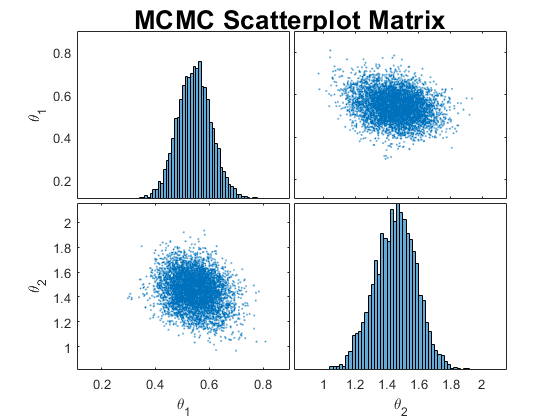

% This is produce the matrix and scatter plot of the samples obtained via MCMC:

for n1 = 1:NumberOfChains
figure();
[~,ax1] = plotmatrix(samples_mcmc(:,:,n1));
title('MCMC Scatterplot Matrix', 'Fontsize', 20);
for i=1:2
    ax1(i,1).FontSize = 10; ax1(2,i).FontSize = 10; 
    ax1(1,1).YLim = [0 4.2]; ax1(1,1).XLim = [0 4.2];
    ax1(1,2).YLim = [0 4.2]; ax1(1,2).XLim = [0 4.2];
    ax1(2,1).YLim = [0 4.2]; ax1(2,1).XLim = [0 4.2];
    ax1(2,2).YLim = [0 4.2]; ax1(2,2).XLim = [0 4.2];
    ylabel(ax1(i,1),sprintf('\\theta_{%d}', i));
    xlabel(ax1(2,i),sprintf('\\theta_{%d}', i));
end
set(gca,'FontSize',18)
end

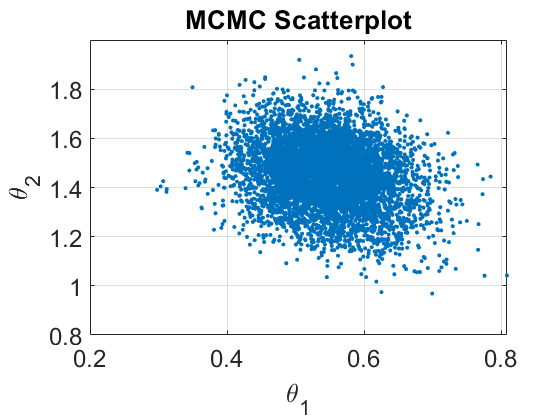


for n2 = 1:NumberOfChains
figure;
scatter(samples_mcmc(:,1,n2), samples_mcmc(:,2,n2), 10, 'filled');
box on
grid on
title('MCMC Scatterplot', 'Fontsize', 20)
xlabel('\theta_1', 'Fontsize', 20);
ylabel('\theta_2', 'Fontsize', 20);
set(gca,'FontSize',18)
end


mcmc_mean_theta1 = mean(samples_mcmc(:,1)); % To calculate sample mean of theta_1
mcmc_std_theta1 = std(samples_mcmc(:,1));   % To calculate sample standard deviation of theta_1

fprintf('The mean of theta_1 obtained via MCMC is: %4.2f, with standard deviation: %4.2f. \n',mcmc_mean_theta1,mcmc_std_theta1)

The mean of theta_1 obtained via MCMC is: 0.55, with standard deviation: 0.06. 


% To display in the Command Window the mean and standard deviation of theta_1 obtained via the MCMC sampler.

mcmc_mean_theta2 = mean(samples_mcmc(:,2)); % To calculate sample mean of theta_2
mcmc_std_theta2 = std(samples_mcmc(:,2));   % To calculate sample standard deviation of theta_2

fprintf('The mean of theta_2 obtained via MCMC is: %4.2f, with standard deviation: %4.2f. \n',mcmc_mean_theta2,mcmc_std_theta2)

The mean of theta_2 obtained via MCMC is: 1.45, with standard deviation: 0.13. 


% To display in the Command Window the mean and standard deviation of theta_2 obtained via the MCMC sampler.

Percentage_error_mcmc_theta1 = (mcmc_std_theta1/mcmc_mean_theta1)*100;
Percentage_error_mcmc_theta2 = (mcmc_std_theta2/mcmc_mean_theta2)*100;

fprintf('The percentage error of the estimation of theta_1 via MCMC is: %4.2f percent \n', Percentage_error_mcmc_theta1)

The percentage error of the estimation of theta_1 via MCMC is: 11.71 percent 


% To display in the Command Window the percentage error of the estimation of theta_1 obtained by the MCMC sampler.

fprintf('The percentage error of the estimation of theta_2 via MCMC is: %4.2f percent \n', Percentage_error_mcmc_theta2)

The percentage error of the estimation of theta_2 via MCMC is: 9.12 percent 


% To display in the Command Window the percentage error of the estimation of theta_2 obtained by the MCMC sampler.

As a check for convergence of the samples, a Time-series plot can be plotted to observe the sample values obtained for $\theta_1$ and $\theta_2$. This can be used to observe the convergence of the sample values with respect to its mean value as well as its associated uncertainty ($1$ standard deviation). 

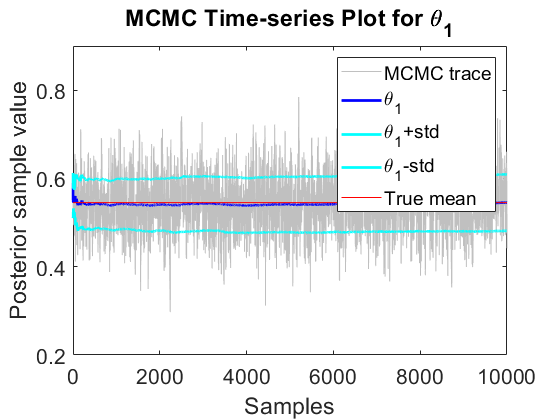

% Compute cumulative mean and variance for MCMC samples of theta_1:
dim=1; 
samples_mcmc_1 = samples_mcmc(:,1,:);

for n=1:size(samples_mcmc_1,2)
% Note: size(samples_mcmc_1,2) accounts for the dimension number of the samples.

% Transpose matrix of samples for counting as a function of number of sample:
samples_mcmc_1T=transpose(squeeze(samples_mcmc_1(:,n,:)));

allSamples_1=samples_mcmc_1(1:numel(samples_mcmc_1T));

if isrow(allSamples_1)
    allSamples_1=transpose(allSamples_1);
end

cumcountMCMC_1 = 1:size(allSamples_1,dim);

cummeanMCMC_1 = bsxfun(@rdivide, cumsum(allSamples_1)', cumcountMCMC_1);
cumvarMCMC_1 = bsxfun(@rdivide, cumsum((allSamples_1 - mcmc_mean_theta1).^2)', (cumcountMCMC_1-1));
cumstdMCMC_1 = sqrt(cumvarMCMC_1);

% This is to plot the Time-series plot of samples for theta_1 obtained via MCMC:
figure;
p1=plot(cumcountMCMC_1,allSamples_1);
p1.Color='#C0C0C0'; % Set gray color
hold on;
plot(cumcountMCMC_1,cummeanMCMC_1,'LineWidth',2,"Color",'b');
plot(cumcountMCMC_1,cummeanMCMC_1+cumstdMCMC_1,'LineWidth',2,"LineStyle","-","Color",'c');
plot(cumcountMCMC_1,cummeanMCMC_1-cumstdMCMC_1,'LineWidth',2,"LineStyle","-","Color",'c');
mu1 = mean(samples_mcmc(:,1));
hline = refline([0 mu1]); % This plots the reference line denoting the mean value of the samples
hline.Color = 'r';
title('MCMC Time-series Plot for \theta_1')
legend('MCMC trace','\theta_1','\theta_1+std','\theta_1-std','True mean')
xlabel('Samples');
ylabel('Posterior sample value');
set(gca,'FontSize',16)
end

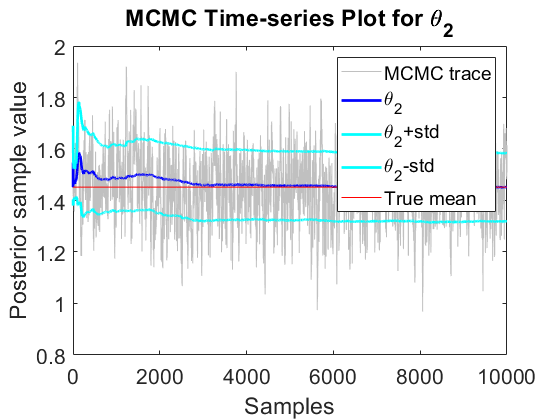



% Compute cumulative mean and variance for MCMC samples of theta_2:
samples_mcmc_2 = samples_mcmc(:,2,:);

for m=1:size(samples_mcmc_2,2)
% Note: size(samples_mcmc_2,2) accounts for the dimension number of the samples.

% Transpose matrix of samples for counting as a function of number of sample:
samples_mcmc_2T=transpose(squeeze(samples_mcmc_2(:,m,:)));

allSamples_2=samples_mcmc_2(1:numel(samples_mcmc_2T));

if isrow(allSamples_2)
    allSamples_2=transpose(allSamples_2);
end

cumcountMCMC_2 = 1:size(allSamples_2,dim);

cummeanMCMC_2 = bsxfun(@rdivide, cumsum(allSamples_2)', cumcountMCMC_2);
cumvarMCMC_2 = bsxfun(@rdivide, cumsum((allSamples_2 - mcmc_mean_theta2).^2)', (cumcountMCMC_2-1));
cumstdMCMC_2 = sqrt(cumvarMCMC_2);

% This is to plot the Time-series plot of samples for theta_2 obtained via MCMC:
figure;
p2=plot(cumcountMCMC_2,allSamples_2);
p2.Color='#C0C0C0'; % Set gray color
hold on;
plot(cumcountMCMC_2,cummeanMCMC_2,'LineWidth',2,"Color",'b');
plot(cumcountMCMC_2,cummeanMCMC_2+cumstdMCMC_2,'LineWidth',2,"LineStyle","-","Color",'c');
plot(cumcountMCMC_2,cummeanMCMC_2-cumstdMCMC_2,'LineWidth',2,"LineStyle","-","Color",'c');
mu2 = mean(samples_mcmc(:,2));
hline = refline([0 mu2]); % This plots the reference line denoting the mean value of the samples
hline.Color = 'r';
title('MCMC Time-series Plot for \theta_2')
legend('MCMC trace','\theta_2','\theta_2+std','\theta_2-std','True mean')
xlabel('Samples');
ylabel('Posterior sample value');
set(gca,'FontSize',16)
end

#### 3.1.4) MCMC Model Update

This is to plot the updated model from the MCMC results.

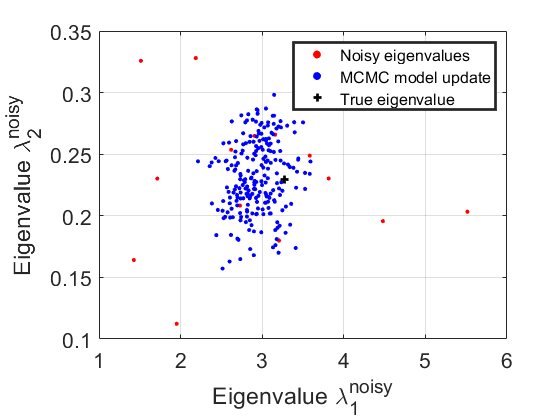

% To plot the 2D scatter plot of the model:
figure;
h1 = scatter(Eigenvalues(:,1,:), Eigenvalues(:,2,:), 10, 'r', 'filled');
box on
grid on
hold on
MCMC_Update = EigenvaluesPerfect(samples_mcmc);
scatter(MCMC_Update(:,1), MCMC_Update(:,2), 10, 'b', 'filled');
legend('Noisy eigenvalues', 'MCMC model update','Fontsize',12, 'LineWidth',2)
plot(3.2702, 0.2293, 'k +',"LineWidth", 2,'DisplayName','True eigenvalue');
xlabel('Eigenvalue \lambda^{noisy}_1','FontSize',20)
ylabel('Eigenvalue \lambda^{noisy}_2','FontSize',20)
set(gca,'FontSize',16)
hold off

### 3.2) Transitional Markov Chain Monte Carlo (TMCMC)

TMCMC is a sampling method which obtains samples through "Transitional" distributions, $P_j$, instead of obtaining samples directly from the Posterior distribution itself. These "Transitional" distributions are defined as such:


$$P_j \propto P(D|\mathbf{\theta})^{\beta_j} \cdot P(\mathbf{\theta})$$


whereby $j$ denotes the iteration number, and $\beta_j$ is the scaling factor such that $0 = \beta_0 < \beta_1<...<\beta_{m-1}<\beta_m=1$with $m$ denoting the last iteration number. As such, the TMCMC sampler works by sampling from the Prior distribution, $P_0 \propto P(\mathbf{\theta})$, at the initial stage ($j=0$), and then obtaining samples from the intermediate "Transitional" distributions through the iterations before finally obtaining samples from the Posterior, $P_m \propto P(\mathbf{\theta}|D)$, at the very last iteration ($j=m$).

This method is particularly useful especially when sampling from a Posterior whose distribution function is complicated, such as having multiple nodes or has a high number of dimensions. More information can be found in the literature by [Ching and Chen (2007)](https://ascelibrary.org/doi/10.1061/%28ASCE%290733-9399%282007%29133%3A7%28816%29). Details to the algorithm for sampling from a 2D posterior can be found in Algorithm 5 of the tutorial paper.

To initiate the TMCMC sampler, the number of samples (Nsamples_tmcmc) to obtain from the Posterior distribution, $P(\mathbf{\theta}|D)$, is to be defined.

% Defining the variables: 
Nsamples_tmcmc = 1000;     % Number of samples to be obtained from the Posterior.

#### 3.2.1) Initiate and Execute the TMCMC sampler

The TMCMC sampler is executed by calling out the external TMCMC function handle which can be found in the file titled: "TMCMCsampler.m".

tic; % To commence the timer.

samples_tmcmc = TMCMCsampler('nsamples',Nsamples_tmcmc,'loglikelihood',log_l,'priorpdf',prior_pdf,'priorrnd',rnd_k,'burnin',0,'lastburnin',0);

timeTMCMC=toc; % To stop the timer.

fprintf('Time elapsed is for the TMCMC sampler: %f \n',timeTMCMC)
% To display in the Command Window that the time elapsed refers to the time
% taken for the TMCMC sampler to obtain samples.

#### 3.2.2) Analysis of the samples obtained via TMCMC sampler

A matrix plot and scatter plot of the samples is obtained to study the 2D distribution of the samples from the 2D Posterior distribution, $P(\mathbf{\theta}|D)$, as well as the marginal distribution of the samples in each of the $2$ coordinates. This is achieved using the [plotmatrix](https://uk.mathworks.com/help/matlab/ref/plotmatrix.html) and [scatter ](https://uk.mathworks.com/help/matlab/ref/scatter.html)functions.

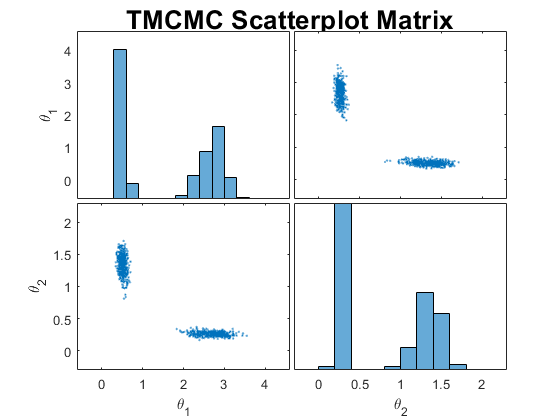

% This is produce the matrix and scatter plot of the samples obtained via TMCMC:
figure;
[~,ax2] = plotmatrix(samples_tmcmc);
title('TMCMC Scatterplot Matrix', 'Fontsize', 20);
for i=1:2
    ax2(i,1).FontSize = 10; ax2(2,i).FontSize = 10; 
    ax2(1,1).YLim = [0 4.2]; ax2(1,1).XLim = [0 4.2];
    ax2(1,2).YLim = [0 4.2]; ax2(1,2).XLim = [0 4.2];
    ax2(2,1).YLim = [0 4.2]; ax2(2,1).XLim = [0 4.2];
    ax2(2,2).YLim = [0 4.2]; ax2(2,2).XLim = [0 4.2];
    ylabel(ax2(i,1),sprintf('\\theta_{%d}', i));
    xlabel(ax2(2,i),sprintf('\\theta_{%d}', i));
end
set(gca,'FontSize',18)

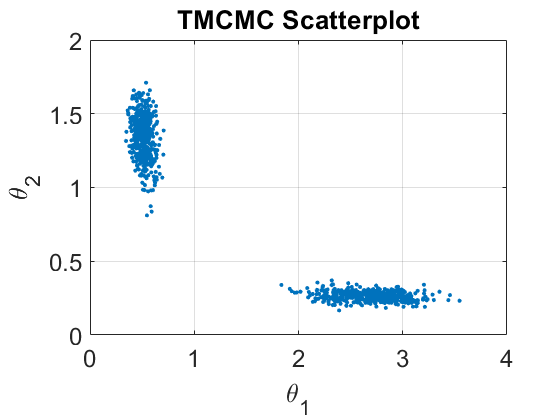


figure;
scatter(samples_tmcmc(:,1), samples_tmcmc(:,2),10,'filled');
box on
grid on
title('TMCMC Scatterplot', 'Fontsize', 20)
xlabel('\theta_1', 'Fontsize', 30);
ylabel('\theta_2', 'Fontsize', 30);
set(gca,'FontSize',18)


tmcmc_mean_theta1 = mean(samples_tmcmc(:,1)); % To calculate sample mean of theta_1
tmcmc_std_theta1 = std(samples_tmcmc(:,1));   % To calculate sample standard deviation of theta_1

fprintf('The mean of theta_1 obtained via TMCMC is: %4.2f, with standard deviation: %4.2f. \n',tmcmc_mean_theta1,tmcmc_std_theta1)

The mean of theta_1 obtained via TMCMC is: 1.63, with standard deviation: 1.12. 


% To display in the Command Window the mean and standard deviation of theta_1 obtained via the TMCMC sampler.

tmcmc_mean_theta2 = mean(samples_tmcmc(:,2)); % To calculate sample mean of theta_2
tmcmc_std_theta2 = std(samples_tmcmc(:,2));   % To calculate sample standard deviation of theta_2

fprintf('The mean of theta_2 obtained via TMCMC is: %d, with standard deviation: %d. \n',tmcmc_mean_theta2,tmcmc_std_theta2)

The mean of theta_2 obtained via TMCMC is: 7.957204e-01, with standard deviation: 5.521504e-01. 


% To display in the Command Window the mean and standard deviation of theta_2 obtained via the TMCMC sampler.

Percentage_error_tmcmc_theta1 = (tmcmc_std_theta1/tmcmc_mean_theta1)*100;
Percentage_error_tmcmc_theta2 = (tmcmc_std_theta2/tmcmc_mean_theta2)*100;

fprintf('The percentage error of the estimation of theta_1 via TMCMC is: %4.2f percent \n', Percentage_error_tmcmc_theta1)

The percentage error of the estimation of theta_1 via TMCMC is: 68.48 percent 


% To display in the Command Window the percentage error of the estimation of theta_1 obtained by the TMCMC sampler.

fprintf('The percentage error of the estimation of theta_2 via TMCMC is: %4.2f percent \n', Percentage_error_tmcmc_theta2)

The percentage error of the estimation of theta_2 via TMCMC is: 69.39 percent 


% To display in the Command Window the percentage error of the estimation of theta_2 obtained by the TMCMC sampler.

As a check for convergence of the samples, a Time-series plot can be plotted to observe the sample values obtained for $\theta_1$ and $\theta_2$. This can be used to observe the convergence of the sample values with respect to its mean value as well as its associated uncertainty ($1$ standard deviation). 

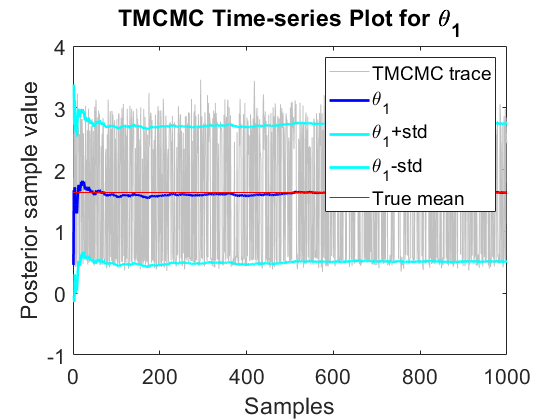

% Compute cumulative mean and variance for TMCMC samples of theta_1:
dim=1; 
cumcountTMCMC_1 = 1:size(samples_tmcmc(:,1),dim);

cummeanTMCMC_1 = bsxfun(@rdivide, cumsum(samples_tmcmc(:,1))', cumcountTMCMC_1);
cumvarTMCMC_1 = bsxfun(@rdivide, cumsum((samples_tmcmc(:,1) - tmcmc_mean_theta1).^2)', (cumcountTMCMC_1-1));
cumstdTMCMC_1 = sqrt(cumvarTMCMC_1);

% This is to plot the Time-series plot of samples for theta_1 obtained via TMCMC:
figure;
p3=plot(cumcountTMCMC_1,samples_tmcmc(:,1));
p3.Color='#C0C0C0'; % Set gray color
hold on;
plot(cumcountTMCMC_1,cummeanTMCMC_1,'LineWidth',2,"Color",'b');
plot(cumcountTMCMC_1,cummeanTMCMC_1+cumstdTMCMC_1,'LineWidth',2,"LineStyle","-","Color",'c');
plot(cumcountTMCMC_1,cummeanTMCMC_1-cumstdTMCMC_1,'LineWidth',2,"LineStyle","-","Color",'c');
mu3 = mean(samples_tmcmc(:,1));
hline = refline([0 mu3]); % This plots the reference line denoting the mean value of the samples
hline.Color = 'r';
title('TMCMC Time-series Plot for \theta_1')
legend('TMCMC trace','\theta_1','\theta_1+std','\theta_1-std','True mean')
xlabel('Samples');
ylabel('Posterior sample value');
set(gca,'FontSize',16)

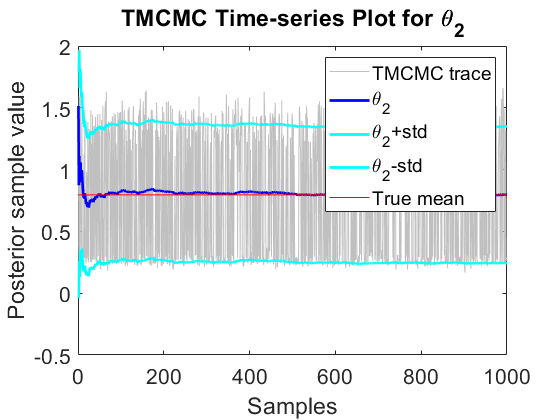


% Compute cumulative mean and variance for TMCMC samples of theta_2:
cumcountTMCMC_2 = 1:size(samples_tmcmc(:,2),dim);

cummeanTMCMC_2 = bsxfun(@rdivide, cumsum(samples_tmcmc(:,2))', cumcountTMCMC_2);
cumvarTMCMC_2 = bsxfun(@rdivide, cumsum((samples_tmcmc(:,2) - tmcmc_mean_theta2).^2)', (cumcountTMCMC_2-1));
cumstdTMCMC_2 = sqrt(cumvarTMCMC_2);

% This is to plot the Time-series plot of samples for theta_2 obtained via TMCMC:
figure;
p4=plot(cumcountTMCMC_2,samples_tmcmc(:,2));
p4.Color='#C0C0C0'; % Set gray color
hold on;
plot(cumcountTMCMC_2,cummeanTMCMC_2,'LineWidth',2,"Color",'b');
plot(cumcountTMCMC_2,cummeanTMCMC_2+cumstdTMCMC_2,'LineWidth',2,"LineStyle","-","Color",'c');
plot(cumcountTMCMC_2,cummeanTMCMC_2-cumstdTMCMC_2,'LineWidth',2,"LineStyle","-","Color",'c');
mu4 = mean(samples_tmcmc(:,2));
hline = refline([0 mu4]); % This plots the reference line denoting the mean value of the samples
hline.Color = 'r';
title('TMCMC Time-series Plot for \theta_2')
legend('TMCMC trace','\theta_2','\theta_2+std','\theta_2-std','True mean')
xlabel('Samples');
ylabel('Posterior sample value');
set(gca,'FontSize',16)

#### 3.2.3) TMCMC Model Update

This is to plot the updated model from the TMCMC results.

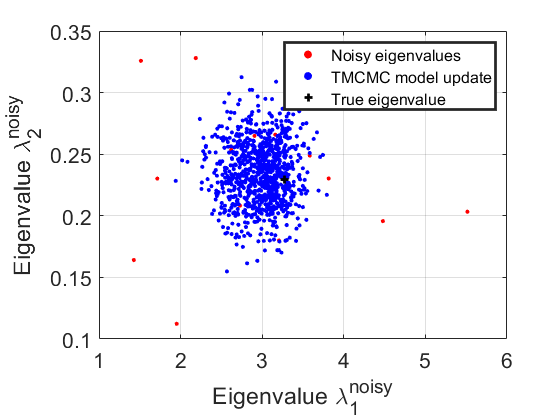

% To plot the 2D scatter plot of the model:
figure;
h1 = scatter(Eigenvalues(:,1), Eigenvalues(:,2), 10, 'r', 'filled');
box on
grid on
hold on
TMCMC_Update = EigenvaluesPerfect(samples_tmcmc);
scatter(TMCMC_Update(:,1), TMCMC_Update(:,2), 10, 'b', 'filled');
legend('Noisy eigenvalues', 'TMCMC model update','Fontsize', 12, 'LineWidth',2)
plot(3.2702, 0.2293, 'k +',"LineWidth", 2,'DisplayName','True eigenvalue');
xlabel('Eigenvalue \lambda^{noisy}_1','FontSize',20)
ylabel('Eigenvalue \lambda^{noisy}_2','FontSize',20)
set(gca,'FontSize',16)
hold off

### 3.3) Sequential Monte Carlo (SMC)

The SMC sampler adopts a recursive sampling algorithm that is based on the Sequential Monte Carlo method (also known as [Particle Filters](https://www.jstor.org/stable/2669847?seq=1#metadata_info_tab_contents)) and it is particularly useful in addressing Bayesian updating problems involving large data sets. An advantage of the SMC sampler is that it can be used to sample from static and dynamical Target distributions. It utilises two main sampling methods in its algorithm: Importance sampling, and Re-sampling. More details can be found in the literatures by [Moral et. al](https://www.jstor.org/stable/3879283?seq=1#metadata_info_tab_contents) and [Green et. al](https://www.sciencedirect.com/science/article/pii/S0888327016305520). Details to the algorithm for sampling from a 2D posterior can be found in Algorithm 8 of the tutorial paper.

To initiate the sampler, the number of samples to obtain from the Posterior distribution (Nsamples_smc), is to be defined. 

The number of samples (Nsamples_smc) parameter defines the sample size to be obtained from the Posterior distribution, $P(\mathbf{\theta}|D)$.

% Defining the variables: 
Nsamples_smc = 10000; % Number of samples to be obtained.

#### 3.3.1) Initiate and Execute the SMC sampler

The SMC sampler is executed by calling out the external SMC function handle which can be found in the file titled: "SMCsampler.m".

Note: As there are no additional model inputs other than the estimated parameters ($\theta_1$ and $\theta_2$), the 'model input' argument in the SMC sampler can be set as a [missing](https://uk.mathworks.com/help/matlab/ref/missing.html?s_tid=doc_ta) variable.

tic; % To commence the timer.

% To initiate the SMC sampler:
smc = SMCsampler('nsamples', Nsamples_smc,'loglikelihoods', {log_l},...
                 'priorpdf', prior_pdf, 'priorrnd', rnd_k);
samples_smc = smc.samples;   


timeSMC = toc; % To stop the timer.

fprintf('Time elapsed is for the SMC sampler: %f \n',timeSMC)
% To display in the Command Window that the time elapsed refers to the time
% taken for the SMC sampler to obtain samples.

#### 3.3.2) Analysis of the samples obtained via SMC sampler

A matrix plot and scatter plot of the samples is obtained to study the 2D distribution of the samples from the 2D Posterior distribution, $P(\mathbf{\theta}|D)$, as well as the marginal distribution of the samples in each of the $2$ coordinates. This is achieved using the [plotmatrix](https://uk.mathworks.com/help/matlab/ref/plotmatrix.html) and [scatter ](https://uk.mathworks.com/help/matlab/ref/scatter.html)functions.

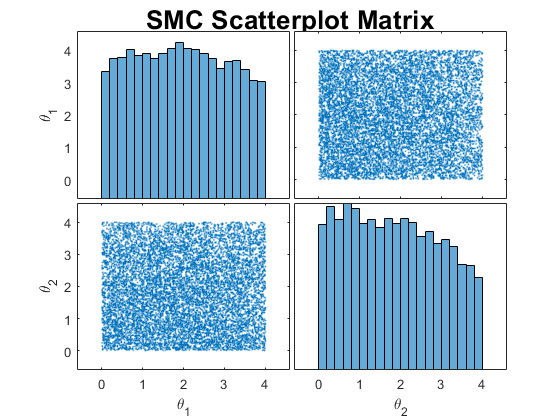

% This is produce the matrix and scatter plot of the samples obtained via TMCMC:
figure;
[~,ax3] = plotmatrix(samples_smc);
%title('SMC Scatterplot Matrix', 'Fontsize', 20);
for i=1:2
    ax3(i,1).FontSize = 10; ax3(2,i).FontSize = 10; 
    ax3(1,1).YLim = [0 4.2]; ax3(1,1).XLim = [0 4.2];
    ax3(1,2).YLim = [0 4.2]; ax3(1,2).XLim = [0 4.2];
    ax3(2,1).YLim = [0 4.2]; ax3(2,1).XLim = [0 4.2];
    ax3(2,2).YLim = [0 4.2]; ax3(2,2).XLim = [0 4.2];
    ylabel(ax3(i,1),sprintf('\\theta_{%d}', i));
    xlabel(ax3(2,i),sprintf('\\theta_{%d}', i));
end
set(gca,'FontSize',18)

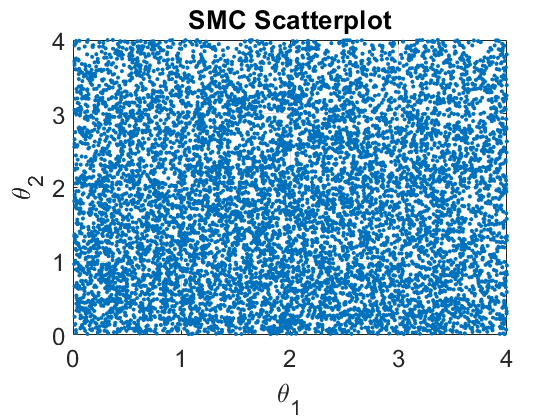


figure;
scatter(samples_smc(:,1), samples_smc(:,2), 10, 'filled');
box on
grid on
title('SMC Scatterplot', 'Fontsize', 20)
xlabel('\theta_1', 'Fontsize', 30);
ylabel('\theta_2', 'Fontsize', 30);
set(gca,'FontSize',18)


smc_mean_theta1 = mean(samples_smc(:,1)); % To calculate sample mean of theta_1
smc_std_theta1 = std(samples_smc(:,1));   % To calculate sample standard deviation of theta_1

fprintf('The mean of theta_1 obtained via SMC is: %4.2f, with standard deviation: %4.2f. \n',smc_mean_theta1,smc_std_theta1)

The mean of theta_1 obtained via SMC is: 1.96, with standard deviation: 1.12. 


% To display in the Command Window the mean and standard deviation of theta_1 obtained via the SMC sampler.

smc_mean_theta2 = mean(samples_smc(:,2)); % To calculate sample mean of theta_2
smc_std_theta2 = std(samples_smc(:,2));   % To calculate sample standard deviation of theta_2

fprintf('The mean of theta_2 obtained via SMC is: %4.2f, with standard deviation: %4.2f. \n',smc_mean_theta2,smc_std_theta2)

The mean of theta_2 obtained via SMC is: 1.86, with standard deviation: 1.12. 


% To display in the Command Window the mean and standard deviation of theta_2 obtained via the SMC sampler.

Percentage_error_smc_theta1 = (smc_std_theta1/smc_mean_theta1)*100;
Percentage_error_smc_theta2 = (smc_std_theta2/smc_mean_theta2)*100;

fprintf('The percentage error of the estimation of theta_1 via SMC is: %d percent \n', Percentage_error_smc_theta1)

The percentage error of the estimation of theta_1 via SMC is: 5.733994e+01 percent 


% To display in the Command Window the percentage error of the estimation of theta_1 obtained by the SMC sampler.

fprintf('The percentage error of the estimation of theta_2 via SMC is: %d percent \n', Percentage_error_smc_theta2)

The percentage error of the estimation of theta_2 via SMC is: 6.012141e+01 percent 


% To display in the Command Window the percentage error of the estimation of theta_2 obtained by the SMC sampler.

As a check for convergence of the samples, a Time-series plot can be plotted to observe the sample values obtained for $\theta_1$ and $\theta_2$. This can be used to observe the convergence of the sample values with respect to its mean value as well as its associated uncertainty ($1$ standard deviation). 

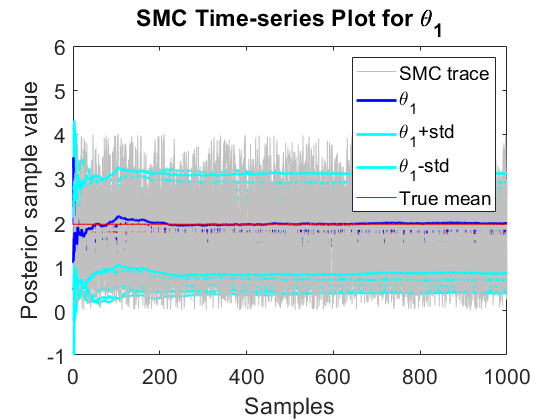

% Compute cumulative mean and variance for SMC samples of theta_1:
dim=1; 
cumcountSMC_1 = 1:size(samples_smc(:,1),dim);

cummeanSMC_1 = bsxfun(@rdivide, cumsum(samples_smc(:,1))', cumcountSMC_1);
cumvarSMC_1 = bsxfun(@rdivide, cumsum((samples_smc(:,1) - smc_mean_theta1).^2)', (cumcountSMC_1-1));
cumstdSMC_1 = sqrt(cumvarSMC_1);

% This is to plot the Time-series plot of samples for theta_1 obtained via SMC:
figure(8);
p5=plot(cumcountSMC_1,samples_smc(:,1));
p5.Color='#C0C0C0'; % Set gray color
hold on;
plot(cumcountSMC_1,cummeanSMC_1,'LineWidth',2,"Color",'b');
plot(cumcountSMC_1,cummeanSMC_1+cumstdSMC_1,'LineWidth',2,"LineStyle","-","Color",'c');
plot(cumcountSMC_1,cummeanSMC_1-cumstdSMC_1,'LineWidth',2,"LineStyle","-","Color",'c');
mu5 = mean(samples_smc(:,1));
hline = refline([0 mu5]); % This plots the reference line denoting the mean value of the samples
hline.Color = 'r';
title('SMC Time-series Plot for \theta_1')
legend('SMC trace','\theta_1','\theta_1+std','\theta_1-std','True mean')
xlabel('Samples');
ylabel('Posterior sample value');
set(gca,'FontSize',16)

xlim([0 1000])
ylim([-1.00 6.00])

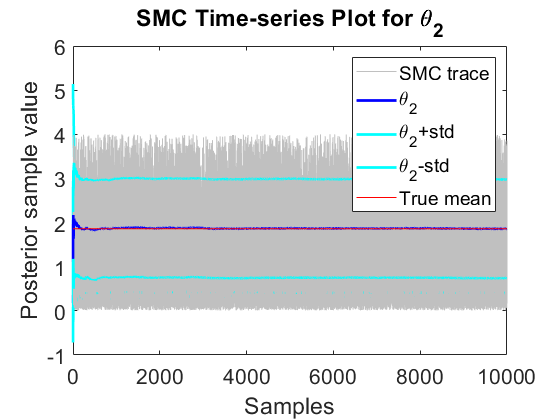


% Compute cumulative mean and variance for SMC samples of theta_2:
cumcountSMC_2 = 1:size(samples_smc(:,2),dim);

cummeanSMC_2 = bsxfun(@rdivide, cumsum(samples_smc(:,2))', cumcountSMC_2);
cumvarSMC_2 = bsxfun(@rdivide, cumsum((samples_smc(:,2) - smc_mean_theta2).^2)', (cumcountSMC_2-1));
cumstdSMC_2 = sqrt(cumvarSMC_2);

% This is to plot the Time-series plot of samples for theta_2 obtained via SMC:
figure(9);
p6=plot(cumcountSMC_2,samples_smc(:,2));
p6.Color='#C0C0C0'; % Set gray color
hold on;
plot(cumcountSMC_2,cummeanSMC_2,'LineWidth',2,"Color",'b');
plot(cumcountSMC_2,cummeanSMC_2+cumstdSMC_2,'LineWidth',2,"LineStyle","-","Color",'c');
plot(cumcountSMC_2,cummeanSMC_2-cumstdSMC_2,'LineWidth',2,"LineStyle","-","Color",'c');
mu6 = mean(samples_smc(:,2));
hline = refline([0 mu6]); % This plots the reference line denoting the mean value of the samples
hline.Color = 'r';
title('SMC Time-series Plot for \theta_2')
legend('SMC trace','\theta_2','\theta_2+std','\theta_2-std','True mean')
xlabel('Samples');
ylabel('Posterior sample value');
set(gca,'FontSize',16)

#### 3.2.3) SMC Model Update

This is to plot the updated model from the SMC results.

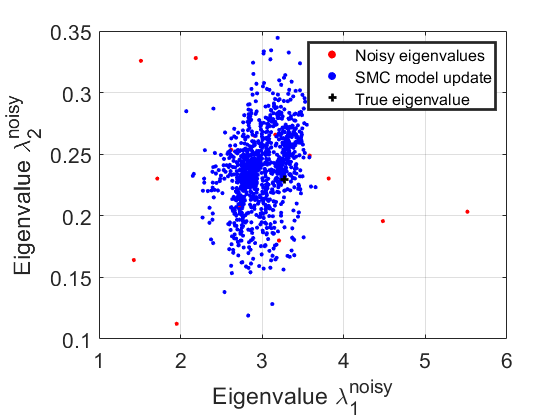

% To plot the 2D scatter plot of the model:
figure;
h1 = scatter(Eigenvalues(:,1), Eigenvalues(:,2), 10, 'r', 'filled');
box on
grid on
hold on
SMC_Update = EigenvaluesPerfect(samples_smc);
scatter(SMC_Update(:,1), SMC_Update(:,2), 10, 'b', 'filled');
legend('Noisy eigenvalues', 'SMC model update','Fontsize',12, 'LineWidth',2)
plot(3.2702, 0.2293, 'k +',"LineWidth", 2,'DisplayName','True eigenvalue');
xlabel('Eigenvalue \lambda^{noisy}_1','FontSize',20)
ylabel('Eigenvalue \lambda^{noisy}_2','FontSize',20)
set(gca,'FontSize',16)
hold off

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% End of Code %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%